% Part 1. Estimate incremental step count from GPS activity tracker

clear
%adding a search path to the data
addpath('ActivityLogs/');

%importing the values
GPS = readtable("GPS.csv");

%creating arrays with the values of the lontitude, lattitude, and timestamp
lat = GPS.latitude;
long = GPS.longitude;
GPStime = GPS.Timestamp;

%creating the Haversine function (should be at the bottm but surely its fine) 

function degrees_traveled = calculate_degrees_traveled(lat1, lon1, lat2, lon2)

    % Convert latitude and longitude from degrees to radians.
    lat1_rad = deg2rad(lat1);
    lon1_rad = deg2rad(lon1);
    lat2_rad = deg2rad(lat2);
    lon2_rad = deg2rad(lon2); 


    % Haversine formula to calculate the distance in radians.
    
    a = (sin((lat2_rad - lat1_rad)/2)^2) + cos(lat1_rad)*cos(lat2_rad)*(sin((lon2_rad-lon1_rad)/2)^2);
    d = 2*atan2(sqrt(a), sqrt(1-a));

    % Convert the distance from radians to degrees.
    degrees_traveled = rad2deg(d);

end

%calculating the distance travelled

%allocating initial variables 
circumference = 40075000; %earths circumference
stride = 0.75; %average stride length of indiviudals
totalDistance = 0;

%creating arrays of distance travelled and steps 
distance_array = (zeros(1,length(GPS.Timestamp)))';
steps_array = zeros(length(GPS.Timestamp),1);

% Number of loops/calculations
n = length(lat) - 1;

% For loop below
for i = 1 : n
    
    % Define lat/long
    lat1 = lat(i);
    lat2 = lat(i+1);

    long1 = long(i);
    long2 = long(i+1);

    % Calculate degrees traveled b/w two coordinates
    d = calculate_degrees_traveled(lat1, long1, lat2,long2);

    % Calculate distance between two coordinates
    distance = (d*circumference)/360 ;

    %total distance 
    totalDistance = totalDistance + distance;

    %total steps 
    steps_array(i+1) = totalDistance/stride;

    % add values to distance array
    distance_array(i+1) = totalDistance;
    
end

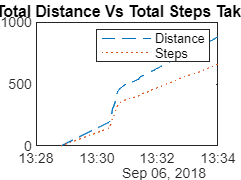

%plotting the values 

ylabel("Total Distance ")
plot(GPStime, steps_array,"--", GPStime, distance_array,":")
title("Total Distance Vs Total Steps Taken")
legend("Distance", "Steps")

**Discussion 1: **

The total distance and the steps are quite similar becuase the steps are a function of the distance travelled. The steps are calculated by dividing the total distance by the number of steps.

They are also proportional to each other; when the distance increases the number of steps taken to cover that distance will also increase. 

**Discussion 2:**

Determining the stride length from a runners pace will create substantially more accurate results, especially when the distance increases. The impacts will be larger if the distance ran is larger. 

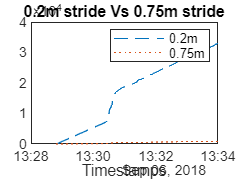

steps2_array = steps_array*0.75;
steps2_array = steps2_array/0.02;


plot(GPStime, steps2_array,"--", GPStime, steps_array, ":")
title("0.2m stride Vs 0.75m stride")
xlabel("Timestamps")
legend("0.2m", "0.75m")

%Part 2

#### Loading the data into variables

%clear all previous data
clear

%path to where data is stored
addpath("ActivityLogs\HRdata\");

%saving data into variables
unknown = readtable("unknownAccHR.csv");
running = readtable("runningAccHR.csv");
walking = readtable("walkingAccHR.csv");
sitting = readtable("sittingAccHR.csv");

#### Combining all known data to train model

%combine data to train model with
allAccelerations = [running; sitting; walking];

classificationLearner

#### Predictions made by models

load("p2_variables.mat")
% Use model that predicts only using XYZ
yfit_XYZ = XYZ_Model.predictFcn(unknown);
% See the first few rows of the predicted classification
head(yfit_XYZ);

    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}



load("p2_variables.mat")
% Use model that predicts only using HR
yfit_HR = HR_model.predictFcn(unknown);
% See the first few rows of the predicted classification
head(yfit_HR);

    {'sitting'}
    {'walking'}
    {'walking'}
    {'running'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}



load("p2_variables.mat")
% Use model that predicts using all XYZ and HR
yfit_HR_XYZ = XYZ_HR_model.predictFcn(unknown);
% See the first few rows of the predicted classification
head(yfit_HR_XYZ);

    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}
    {'walking'}



#### Duplicate unknown data and add predicted data

% Duplicate the table
unknown2 = unknown;

% Append trained HR and XYZ data to the new table
unknown2.Activity = yfit_HR_XYZ;

% Duplicate the table
unknown3 = unknown;

% Append trained HR data to the new table
unknown2.Activity = yfit_HR;

% Duplicate the table
unknown4 = unknown;

% Append trained XYZ data to the new table
unknown4.Activity = yfit_XYZ;

#### Graph data to compare predictions

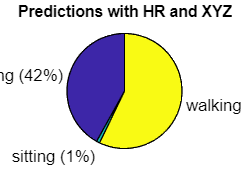

% Create pie chart of predicted activities
pie(categorical(yfit_HR_XYZ));
title("Predictions with HR and XYZ")

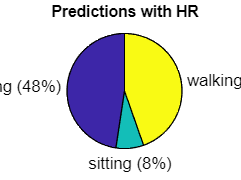

% Create pie chart of predicted activities
pie(categorical(yfit_HR));
title("Predictions with HR")

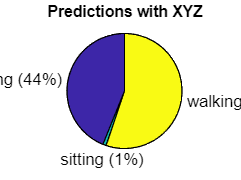

% Create pie chart of predicted activities
pie(categorical(yfit_XYZ));
title("Predictions with XYZ")

#### Most suitable prediction model

The model that uses both HR and XYZ data is the model that is most suitable for predicting activity type. The more data the ML has to learn from the better it will perform in predicting unknown values.

#### Limitation of using HR data

There could be a lot of potential drawbacks of using HR data as the sole predictor as your heart rate increases in many scenarios that are not just related to running like fear or anxiety and other emotions that increase adrenaline.

#### Use of GPS data in classifying activity

Yes, it will help the model predict better as a sitting person wouldn't have a lot of change in long/lat, but someone running would have a more rapidly changing lat/long.